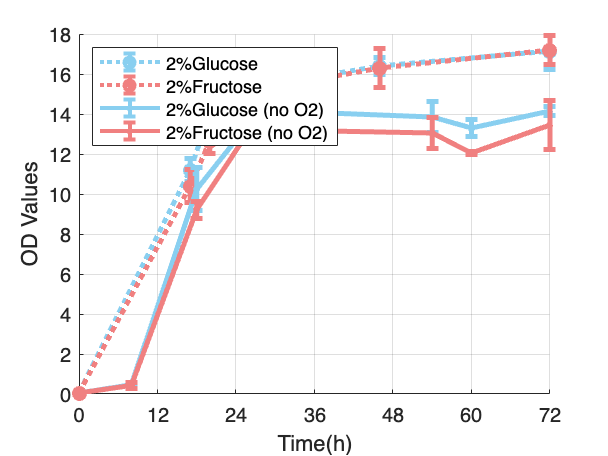

% Common Data Reading and Initialization
filename = 'WT S.B Growth Curve Data.xlsx';

% 1. Read the Data from First Sheet
[data1, text1] = xlsread(filename, 1);
time1 = data1(:, 1);
conditions1 = data1(:, 2:5);

% 2. Read the Data from Second Sheet
[data2, text2] = xlsread(filename, 2);
time2 = data2(:, 1);
conditions2 = data2(:, 2:5);

colors = {'#89CFF0', '#F08080', '#89CFF0', '#F08080'};
%colors = {'#708090', '#008080', '#89CFF0', '#77DD77'}; % Colors for 4 groups
% Create a Figure
figure;
hold on;

% ---------- First Sheet Data ----------

numGroups1 = 2;
stdValues1 = zeros(length(time1), numGroups1);

for i = 1:numGroups1
    col1 = conditions1(:, 2*i-1);
    col2 = conditions1(:, 2*i);
    stdValues1(:, i) = std([col1, col2], 0, 2);
    groupMean1 = mean([conditions1(:, 2*i-1), conditions1(:, 2*i)], 2);
    errorbar(time1, groupMean1, stdValues1(:, i), ':o', 'Color', colors{i}, 'MarkerSize', 5, 'LineWidth', 2.5);
end

% ---------- Second Sheet Data ----------

numGroups2 = 2;
stdValues2 = zeros(length(time2), numGroups2);

for i = 1:numGroups2
    col1 = conditions2(:, 2*i-1);
    col2 = conditions2(:, 2*i);
    stdValues2(:, i) = std([col1, col2], 0, 2);
    groupMean2 = mean([conditions2(:, 2*i-1), conditions2(:, 2*i)], 2);
    errorbar(time2, groupMean2, stdValues2(:, i), '-o', 'Color', colors{i+numGroups1}, 'MarkerSize', 1, 'LineWidth', 2.5);
end

% Legend with the note "no O2" added to entries from the second sheet
legendEntries = [text1(1, 2:4), strcat(text2(1, 2:2), " (no O2)")];

legendEntries = {
    [text1{1, 2}], [text1{1, 4}], [text2{1, 2} ' (no O2)'], [text2{1, 4} ' (no O2)']
};
legend(legendEntries, 'Location', 'northwest');

% Customize the Graph
%title('S.B Growth Curve Oxygen Stress Comparison');
xlabel('Time(h)');
ylabel('OD Values');
ylim([0 18]); % Set y-axis limits from 0 to 18
grid on;

% Set x-axis limits and ticks
xlim([0 72]);
xticks(0:12:72);

% Save the combined graph
saveas(gcf, 'WT_S.B_growth_curve_oxygen_stress_comparison.png');